clear variables;

demo = true;

## Create Numerical Loops

fex = 100;  % excitation frequency (Hz)
N_cycles = 2;
cycle_points = 600;
m = 6000;
noise = 'fft';
random_value_generator = 'more_stick';  % choose a distribution with more 'stick' loops
training_cycles = N_cycles;

cd ..\create_numerical_loops
numerical_loops = create_loops(fex, N_cycles, cycle_points, m, noise, ...
    random_value_generator, training_cycles);


cd ..\experimental_data
load real_loops.mat;
cd ..\mdl_loops

## Classification using the existing model

pct_train = 0;
[~, loops_test, ~, ~, Xtest, ytest] = choose_features(numerical_loops, ...
                                            'slip', pct_train);

load mdl_classification.mat;
y_pred = predict(mdl_classification, Xtest);
fprintf('Precentage of loops those are in stick regime: %0.2f%%\n',...
    nnz(numerical_loops.slip==0)/size(numerical_loops,1)*100);

Precentage of loops those are in stick regime: 44.02%


fprintf('Percentage of loops correctly classified: %0.2f%%\n', ...
            mean(y_pred == ytest)*100);

Percentage of loops correctly classified: 98.85%


        
loops_stick = loops_test(y_pred == 0,:);  % extract loops with gross slip
fprintf('Number of slip: %d | Number of stick: %d\n\n', ...
                            m - size(loops_stick, 1), size(loops_stick, 1));

Number of slip: 3290 | Number of stick: 2710



## Visualise numerical loops

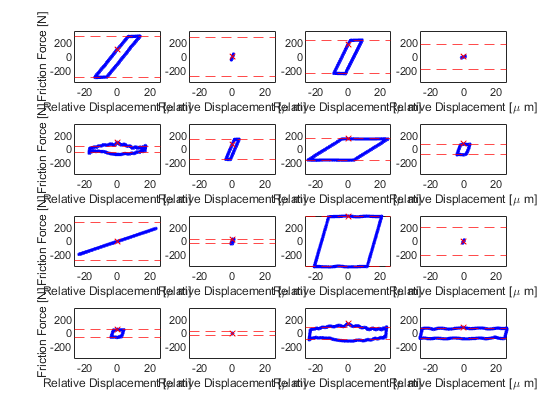

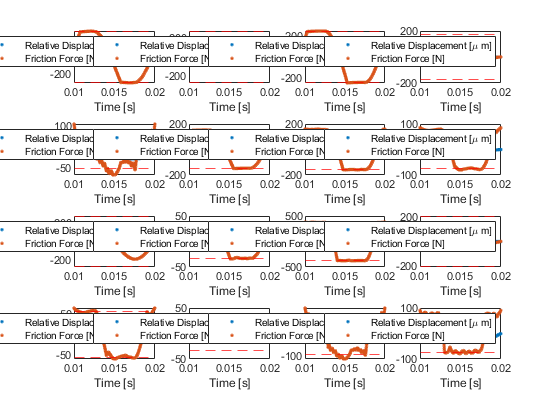

cd ..
normalise = false;
idx = randperm(m, 16);
plot_loops_individual(numerical_loops(idx,:), normalise);

cd mdl_loops

## Choose features

pct_train = 0.8;
[~, loops_test, Xtrain, ytrain, Xtest, ytest] = choose_features(loops_stick, ...
                                            'kt_stick', pct_train);

## Train the model

if ~demo
rng('default');
mdl_kt_stick = fitrsvm(Xtrain, ytrain,...
            'RemoveDuplicates', false, ...
            'Standardize', true, ...
            'KernelFunction', 'gaussian', ...
            'OptimizeHyperparameters', {'KernelScale', 'BoxConstraint', 'Epsilon'},...
            'HyperparameterOptimizationOptions',...
            struct('AcquisitionFunctionName','expected-improvement-plus'))
end

## Evaluate model performance

if demo
    load mdl_kt_stick.mat
    pct_train = 0;
    [~, loops_test, ~, ~, Xtest, ytest] = choose_features(loops_stick, 'kt_stick', pct_train);
end

fprintf('\n========== stick numerical loops ==========\n');


========== stick numerical loops ==========


mean error: 1.14%, highest error: 362.14% at 1780


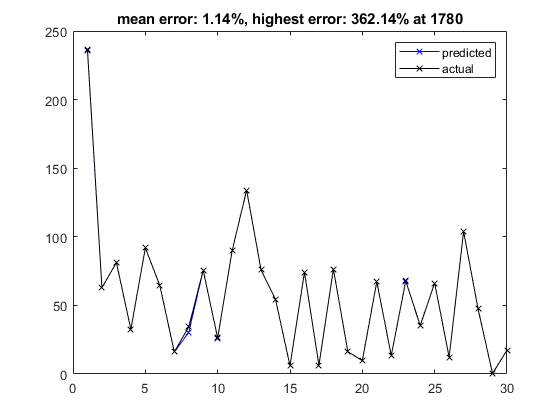

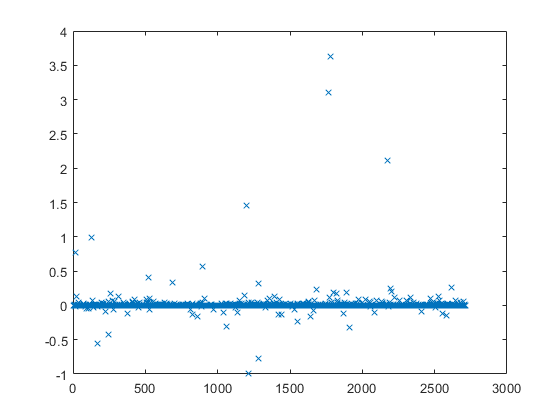

if ~demo
    fprintf('Training error: %0.2f%%\n', ...
                mean(abs((predict(mdl_kt_stick, Xtrain)-ytrain)./ytrain))*100);
end

[y_pred, error] = evaluate_mdl_reg(mdl_kt_stick, Xtest, ytest, demo);